clearvars
freq_array = readtable('./ADC_Data/Board2/11-25-Python-Sweep-1MHz-50%-1020mV/freq_array.csv');
freq_array = table2array(freq_array);
freq_array = floor(freq_array);
%%% Remember to change this! if folder change
filepath = './ADC_Data/Board2/11-25-Python-Sweep-1MHz-50%-1020mV/';
% 1:freq, 2: SNR, 3: SNDR 4:SFDR
BigSet = zeros(length(freq_array),4);
% :length(freq_array)
for i = 1:length(freq_array)
    freq = num2str(freq_array(i));
    BigSet(i,1) = freq_array(i);
    filename = strcat(filepath,'SIN_',num2str(freq_array(i)),'Hz_1020mV---CLK_1MHz_50%.csv');
    data = readtable(filename);
    data_dec = table2array(data);
    % data_dec = data_dec(data_dec ~= 0);
    data_bin = dec2bin(data_dec);
    data_EOC = str2num(data_bin(:,1));
    data_Code = str2num(data_bin(:,2:10));
    data_NewCode = size(length(data_Code),1);
    data_Code_dec = bin2dec(num2str(data_Code));

    rising_edge_indices = find(diff(data_EOC) == 1)+1;

    for k = 1:length(rising_edge_indices)
        index = rising_edge_indices(k);
        data_NewCode(k,1) = data_Code_dec(index);
     
    end


    Fs=1e6;
    num_segments=1;
    f_signal = freq_array(i);
    f_s = Fs;
    BW =500e3;

    % Apply digital filter
    data_NewDec = data_NewCode;
    % data_NewDec = floor(medfilt1(data_NewCode, 20));
    % data_NewDec = EMA_filter(data_NewCode);
    % if i < 22 && i > 1
    %     [b, a] = butter(2, 20*freq_array(i)/(f_s/2), 'low'); % Design the filter
    %     data_NewDec = filtfilt(b, a, data_NewCode); % Apply the filter    
    % elseif i == 1
    %     data_NewDec = data_NewCode;
    % else
    %     [b, a] = butter(2, 20*freq_array(i)/(f_s/2), 'low'); % Design the filter
    %     data_NewDec = filtfilt(b, a, data_NewCode);
    % end

    sample_size=2^floor(log2(length(data_NewDec)));
    periodogram_length = sample_size / num_segments;
    fbin = f_s / periodogram_length;
    plotYN = 0; plotAll = 0; plotHold = 0; plotLin = 0; datNorm = 1;
    [sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB,HD2,HD3, SNR, SFDR] = ...
        plot_periodogram_SFDR(data_NewDec, periodogram_length, num_segments, f_signal, ...
        f_s, BW, plotAll, plotHold, plotYN, plotLin,datNorm);
    fprintf('@Freq = %.3f, SNR = %.3f dB, SNDR = %.3f dB, SFDR = %.3f dB, HD2 = %.3f and HD3 = %.3f\n',   f_signal, SNR,SNDR, SFDR, HD2,HD3);
    set(gcf,'color','w')
    BigSet(i,2) = SNR;
    BigSet(i,3) = SNDR;
    BigSet(i,4) = SFDR;
    
    %%%%%% Reconstructed the waveform
    % Parameters
    % fs = 1e6;                 % Sampling rate in Hz
    % N = length(data_NewDec);                  % Number of samples
    % bit_depth = 9;            % ADC bit resolution
    % V_min = 0;              % Minimum input voltage
    % V_max = 1;               % Maximum input voltage
    % 
    % % Map codes to voltage
    % voltages = ((data_NewDec / (2^bit_depth - 1)) * (V_max - V_min)) + V_min;
    % 
    % % Create time axis
    % t = (0:N-1) / fs;
    % 
    % % Plot the reconstructed waveform
    % figure;
    % plot(t, voltages, 'b');
    % title('Reconstructed Time-Domain Waveform');
    % xlabel('Time (s)');
    % ylabel('Amplitude (V)');
    % grid on;
end

@Freq = 1000.000, SNR = 50.754 dB, SNDR = 49.996 dB, SFDR = 62.188 dB, HD2 = 65.385 and HD3 = 62.188
@Freq = 1172.000, SNR = 33.647 dB, SNDR = 32.831 dB, SFDR = 41.325 dB, HD2 = 50.312 and HD3 = 41.325
@Freq = 1373.000, SNR = 33.798 dB, SNDR = 32.743 dB, SFDR = 41.606 dB, HD2 = 52.985 and HD3 = 41.606
@Freq = 1610.000, SNR = 33.824 dB, SNDR = 33.028 dB, SFDR = 41.834 dB, HD2 = 53.761 and HD3 = 41.834
@Freq = 1887.000, SNR = 33.894 dB, SNDR = 33.056 dB, SFDR = 41.860 dB, HD2 = 54.959 and HD3 = 41.860
@Freq = 2212.000, SNR = 33.787 dB, SNDR = 33.008 dB, SFDR = 41.840 dB, HD2 = 56.714 and HD3 = 41.840
@Freq = 2592.000, SNR = 33.756 dB, SNDR = 32.564 dB, SFDR = 41.326 dB, HD2 = 60.045 and HD3 = 41.326
@Freq = 3039.000, SNR = 33.662 dB, SNDR = 32.920 dB, SFDR = 41.888 dB, HD2 = 68.492 and HD3 = 41.888
@Freq = 3562.000, SNR = 33.677 dB, SNDR = 32.894 dB, SFDR = 41.939 dB, HD2 = 61.650 and HD3 = 41.939
@Freq = 4175.000, SNR = 33.892 dB, SNDR = 33.094 dB, SFDR = 42.181 dB, HD2 = 69.179 and HD3

save('BigSet.mat', 'BigSet');

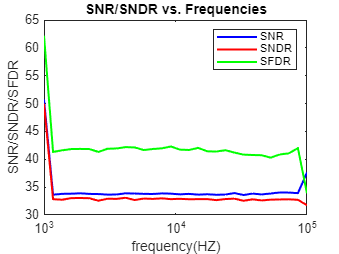

save('BigSet.mat', 'BigSet');
load('BigSet.mat')
figure
semilogx(BigSet(:,1), BigSet(:,2), 'b-', 'LineWidth', 1.5,"DisplayName","SNR");
hold on
semilogx(BigSet(:,1), BigSet(:,3), 'r-', 'LineWidth', 1.5, "DisplayName","SNDR");
semilogx(BigSet(:,1), BigSet(:,4), 'g-', 'LineWidth', 1.5, "DisplayName","SFDR");
hold off
xlabel("frequency(HZ)"); ylabel("SNR/SNDR/SFDR");
title("SNR/SNDR vs. Frequencies");
legend;

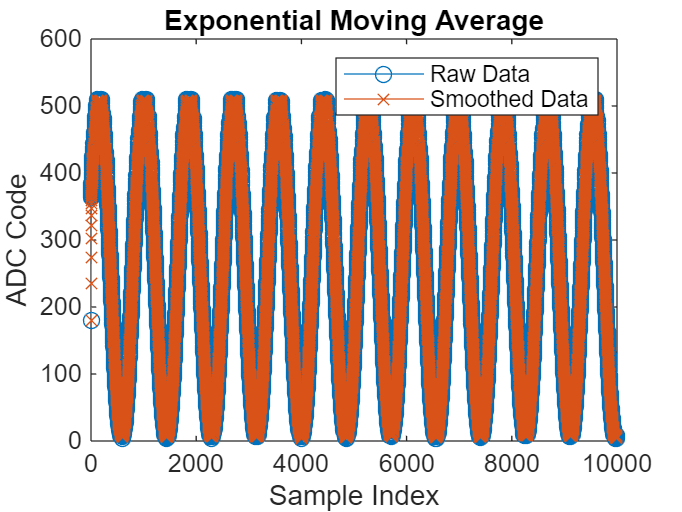

function smoothed_data = EMA_filter(raw_data)
% Parameters
alpha = 0.1; % Smoothing factor (0 < alpha <= 1; smaller = smoother)

% Apply exponential moving average
smoothed_data = zeros(size(raw_data));
smoothed_data(1) = raw_data(1); % Initialize with the first data point
for i = 2:length(raw_data)
    smoothed_data(i) = alpha * raw_data(i) + (1 - alpha) * raw_data(i-1);
end
end